# Bayesian parameter inference of the binding energy $\Delta\epsilon_r
$

In this tutorial we will use the data from  [Garcia & Phillips 2011](http://www.rpgroup.caltech.edu/publications/Garcia2011c.pdf). In this beautiful paper they measured the fold-change in gene expression due to the presence of a transcriptional repressor *lacI* for different binding sites for the repressor.

Using equilibrium statistical mechanics the authors derived a simple expression that describes this phenomena as a function of some of the "natural variables" of the problem such as the repressor copy number per cell $R$ and its binding energy to the operator $\Delta\epsilon_r$. The equation used in this paper is of the form


$$\text{fold-change}  = \left( 1 + \frac{R}{N_{NS}}e^{-\beta\Delta\epsilon_r} \right)^{-1}$$


where $N_{NS}$ represents the number of non-specific (NS) binding sites where the repressor can bind and $\beta \equiv \frac{1}{k_BT}$.

In the paper the authors built *E. coli *strains with different ribosomal binding sites for the repressor gene so that they could vary the mean copy number of this transcription factor in the cell. They then determined experimentaly this mean copy number using quantitative western blots and then measured the gene expression fold-change with respect to a reference strain with **no repressors** present. Our job for this tutorial will be to use these pair of measurements $\{ R, \text{fold-change}\}$ to infer the repressor binding energy $\Delta\epsilon_r$.

## Exploratory data analysis.

The first step on every analysis should always be an exploration of the data. What this means is that we have to get a sense of not only what the data is, but how is it structured. The way in which you format your data can have a huge impact on how you perform your analysis. It is highly recommended to keep your data in what is called a "tidy data frame." We have made this data set tidy already meaning that on each row there is a single measurement with all the relevant information for such measurement. This will make it much easier to manipulate our data.

% Read the data frame containing the experimental measurements
df = readtable('Garcia2011_AbsoluteSinglelacZ_wFC.csv');

% Display 3 specific colums of the data set
df(1:5,{'operator', 'repressors', 'fold_change'})

ans = 5×3 table
    operator    repressors    fold_change
    ________    __________    ___________

    'Oid'       610           0.00022109 
    'O1'        610            0.0012936 
    'O2'        610             0.006133 
    'Oid'        11            0.0066914 
    'O1'         11             0.037764 


The file contains other relevant columns but the ones we just printed into the screen are the important ones for what we are planning to do.

A powerful feature about having tidy data frames is that we can very easily group our data by different criteria. For example let's say I want to generate a log-log plot of $R$ vs $\text{fold-change}$ for the different operators. All I have to do is find the entries for each of the unique operators and plot them in a simple `for` loop. Let's implement that.

% Find unique operators
operators = unique(df.operator)

operators = 4×1 cell array
    {'O1' }
    {'O2' }
    {'O3' }
    {'Oid'}


Before performing the loop to plot the data let's show how we can use the operator column to extract all the data points from a particular operator. Let's say I'm interested in particular in the operator O2. To extract all the data from this operator all I would have to do is find which rows contain O2 in the operator column and then use **boolean indexing** to extract the other columns where this condition is true. Boolean indexing is one of the most powerful tools to work with your data if it is tidy. What this means is that if I want only measurements of a specific type (time points before certain moment, specific cell type, a list of concentrations of drugs, a specific date or whatever other feature of the data) I just have to go row by row and ask "*does this row satisfy my condition?*" and if it does I extract that row. In this case since we have a columns that specifies the operator we will go row and extract the ones that have the opeartor we want to work with.

It used to be the case that one couldn't use Boolean operators such as `==` with strings in Matlab and one had to use a function such as `strcmp` in ordert to perform this boolean comparison. So to extract the rows containing O2 I would have to write something like

`O2Rows = strcmp(df.operator, 'O2');`

But since version 2017a the [string array](https://www.mathworks.com/help/matlab/ref/string.html) data structure was introduced so now if we use double quotes we can use the normal boolean comparision operator. Let's find which rows contain data for O2 and then use those `True` / `False` indices to separate this data.

% Generate a boolean array (i.e. True and False) for where the column operator contains O2 as an entry.
O2Rows = df.operator == "O2";

% Use the boolean array to extract the data for O2 from the general data frame.
% We will extract only the columns we care about to keep it simple.
dfO2 = df(O2Rows, {'operator', 'repressors', 'fold_change'});

% Display the first 5 rows
dfO2(1:5,:)

ans = 5×3 table
    operator    repressors    fold_change
    ________    __________    ___________

    'O2'        610           0.006133   
    'O2'         11            0.17904   
    'O2'          0                  1   
    'O2'        610           0.007307   
    'O2'         11             0.1575   


Great! We just extracted all of the O2 data. Now we can literally just take the `repressors` and `fold_change` columns and plot what we were looking for.

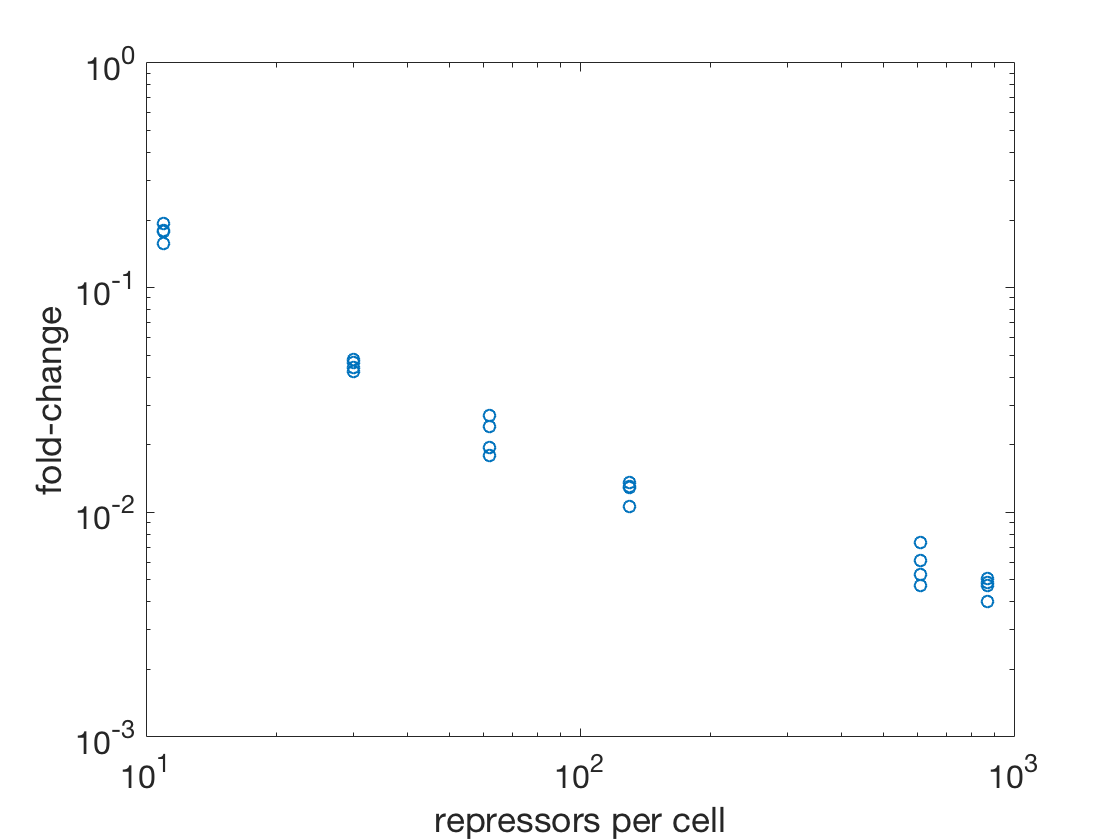

% Plot repressor vs fold-change on a log-log plot.
loglog(dfO2.repressors, dfO2.fold_change, 'o')

% Label axis
xlabel('repressors per cell')
ylabel('fold-change')

% Change the font size
set(gca, 'FontSize', 16)

Another powerful thing about the tidy data frame is that we can compute interesting quantities over groups. For example let's say that we wanted to plot the mean and standard deviation rather than all of the data points for the experimental fold change. What we would need to do is group by repressor copy number and compute both the mean and standard deviation and then plot this as a point with error bars. Matlab has a built-in function to compute statistics by grouping from a table with respect to some column. Let's use it to compute both the mean and standard deviation. The syntax is as follows

`grpstats(table, column used to group, list of statistics to compute, extra arguments)`

Let's then group by repressor copy number and compute the mean and standard deviation of the `fold_change` column.

% Group by repressor copy number and compute the mean fold-change and the standard deviation
statsO2 = grpstats(dfO2, 'repressors', {'mean','std'}, 'DataVars', 'fold_change')

statsO2 = 7×4 table
           repressors    GroupCount    mean_fold_change    std_fold_change
           __________    __________    ________________    _______________

    0        0           11                    1                    0     
    11      11            4              0.17646             0.014342     
    30      30            4             0.045291            0.0024109     
    62      62            4             0.022091            0.0041727     
    130    130            4             0.012513            0.0012798     
    610    610            4             0.005856            0.0011288     
    870    870            4            0.0046656           0.00047479     


Having computed both the mean and standard deviation for each repressor copy number we can now plot this with error bars.

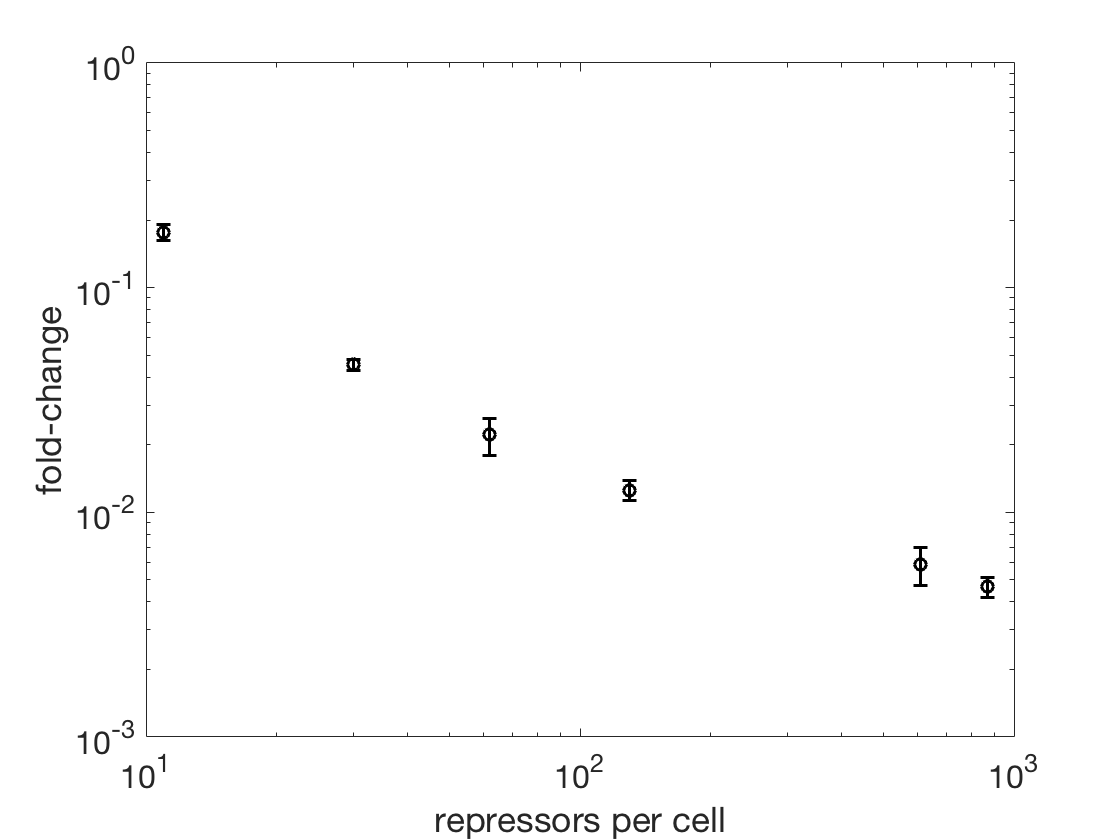

% Plot mean +- std with error bars
errorbar(statsO2.repressors, statsO2.mean_fold_change, statsO2.std_fold_change,...
         'ko', 'Linewidth', 1.5)
     
% Set both axis scale to log
set(gca,'xscale','log')
set(gca,'yscale','log')

% Label axis
xlabel('repressors per cell')
ylabel('fold-change')

% Schange font size
set(gca, 'FontSize', 16)

Our error bars are assymetric on a log plot which is not right, but for now we will ignore this caveat. I just want to highlight that if you ever plot something with error bars on a log scale you need to display the error bars of the log of the quantity you are plotting, not the linear error bars. Keep that in mind for whenever you plan to do this.

Finally before getting into the real objective of this tutorial let's exemplify the power of tidy data frames by reproducing this same plot including all operators available in the data frame. This time we will use `grpstats` to group by two criteria: operator and repressor copy number. We will then compute the mean and standard deviation of the `fold_change` column for each group. In a single step with no nasty `for` loops or anything like that we will be able to plot all of the different operators because of the tidyness of our data!

% Compute the mean and standard deviation of the fold-change grouping by both operator and repressors columns
statsOperator = grpstats(df, {'operator', 'repressors'}, {'mean','std'}, 'DataVars', 'fold_change');

% Display first 5 rows
statsOperator(1:5, :)

ans = 5×5 table
               operator    repressors    GroupCount    mean_fold_change    std_fold_change
               ________    __________    __________    ________________    _______________

    Oid_0      'Oid'         0           11                     1                   0     
    Oid_11     'Oid'        11            4             0.0075997          0.00066052     
    Oid_30     'Oid'        30            4             0.0016416           0.0002045     
    Oid_62     'Oid'        62            4             0.0010601          0.00031438     
    Oid_130    'Oid'       130            4            0.00063515          9.6439e-05     


As far as I know (which I could be completely wrong) MATLAB doesn't have functionalities to plot data automatically grouping by certain criteria. But this is not an issue for us. We will simply use a `for` loop to go through each of the individual operators and plot the mean and standard deviation in fold-change for each of the operators.

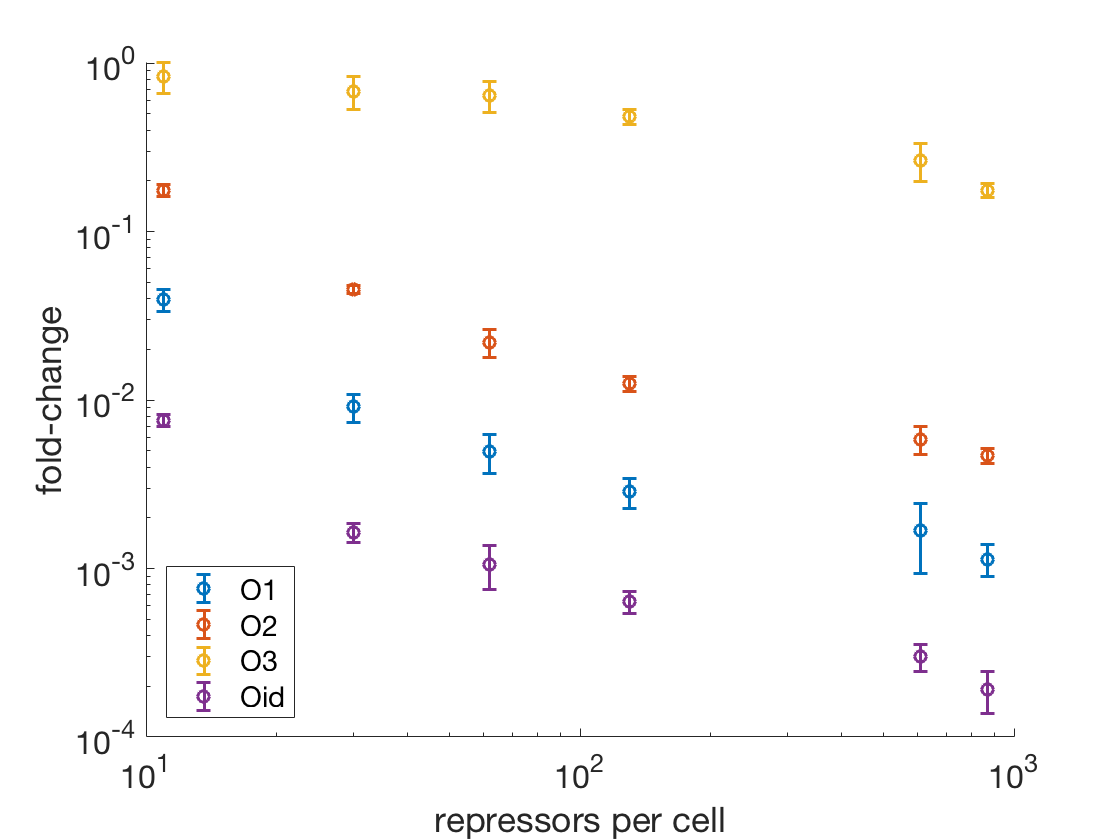

% loop through each operator plotting the fold-change with error bars
figure
hold on
for i=1:length(operators)
    % Find rows for the ith operator
    % NOTE: we have to convert the operator into a string type in order to use
    % the == boolean operator
    opRows = statsOperator.operator == string(operators(i));
    
    % Extract data for that particular operator
    opData = statsOperator(opRows, :);
    
    % Plot fold-change with error bars
    errorbar(opData.repressors, opData.mean_fold_change,...
             opData.std_fold_change, 'o', 'Linewidth', 1.5)   
end %for

% Change bot axis to log scale
set(gca,'xscale','log')
set(gca,'yscale','log')

% Label axis
xlabel('repressors per cell')
ylabel('fold-change')

% Create a legend
legend(operators, 'Location', 'southwest')

% Change font size
set(gca, 'FontSize', 16)
hold off

# Introduction to Bayesian Regression

## This section is based on Justin Bois' fantastic [data analysis course](http://bebi103.caltech.edu/2015) at Caltech.

We highly recommend you to read his [introduction to bayesian parameter estimation](http://bebi103.caltech.edu/2015/lecture_notes/l02_parameter_estimation.pdf) to learn with more details what we will present here. Due to time constraints we will just go through a short primer on the topic.

As we mentioned during lecture for Bayesians probability is a *measure of plausibility* for any statement. For parameter estimation we want to find the probability distribution of the value of our parameters of interest, i.e. as Bayesians we will never say something like: "*this is the value of the parameter we measure in our experiment with 100% certainty*"; but rather we would report the **probability distribution** of the values that these parameters can take.

Since the parameter we are trying to infer given some data is the binding energy, this can be written in terms of Bayes theorem as


$$P(\Delta \varepsilon_r \mid D) = \frac{P(D \mid \Delta \varepsilon_r)P(\Delta \varepsilon_r)}{P(D)},$$


where $D = \{ d_1, \ldots, d_n \}$ represents our data set. Recall that each term on Bayes theorem has a name commonly used in data analysis


$$\mbox{posterior} = \frac{\mbox{likelihood} \times \mbox{prior}}{\mbox{evidence}}.$$


But note that for our purposes of finding the **posterior probability** of the binding energy given the data the evidence doesn't depend on this parameter. So for this case it is just a normalization constant that we can ignore, giving us


$$P(\Delta \varepsilon_r \mid D) \propto P(D \mid \Delta \varepsilon_r)P(\Delta \varepsilon_r).$$


As researches we **have to make decisions** on what functional forms the likelihood and the prior will take. One of the things I like the most about Bayesian analysis is that every single assumption that goes into the analysis is transparent. Every researcher when performing statistical analysis is making assumptions about the data even when he/she doesn't now it. For example if you have ever used a student-t test you have implicitly assumed that your data is Gaussian distributed. But in the Bayesian framework we are under control of all of these assumptions, making the analysis much more clear.

Let's go ahead and list all of the assumptions that go into our analysis.

# The likelihood $P(D \mid \Delta\epsilon_r)$

The likelihood, as the name indicates, tells us how likely it is that we would have observed our data given certain parameter value. In this case if my binding energy is completely off of what the most likely value is, then this term will be really small indicating that under our assumptions the data that we obtained would be very unlikely to be generated by our model given that parameter value. On the other hand if my binding energy is close to the most likely parameter value, then this term will be high, indicating that this specific choice of binding energy could have likely generated the data that we observed.

Let's list the assumptions that go into this term.

## Every datum is independent of each other

The first safe assumption we will make is that each datum in our data set is completely independent of each other. Given the laws of probability we have the "mantra" that *independence of events means to multiply probabilities**. *What that means mathematically is that we will write the likelihood as


$$P(D \mid \Delta\epsilon_r) = \prod_{d_i \in D} P(d_i \mid \Delta\epsilon_r),$$


where $d_i$ represents the $i^{th}$ datum and $\prod_{d_i \in D}$ is read as the product of each datum $d_i$ in the data set $D$.

## Gaussian likelihood for the deviations from our theoretical predictions

The likelihood contains all the information that we have on how the parameter we are trying to infer relates to our experiment. We could clasify likelihoods in two categories depending on the nature of the model we have for the data:

- The likelihood models the **deviations from the model **given some ***deterministic*** relationship between parameters and data.

- The likelihood itself could be the model if our relationship between parameters and data is **probabilistic**. For example if my model is itself a probability distribution of how I expect to find my data I could use that distribution directly as a model.

Our model falls into the first category. We have a deterministic relationship between binding energy and fold-change, i.e. our model doesn't tell us anything about the deviations from the mean fold-change. If we were interested in these deviations we would have to use a different theoretical framework such as chemical master equations (look at [this interesting review](http://www.ncbi.nlm.nih.gov/pubmed/23557991) by Jane Kondev for more on the use of chemical master equations). This means that our likelihood has to describe the distribution of deviations of the experimental data from our theoretical prediction. Note that for this we are ***assuming that the model indeed describes the data***. Without getting into the philosophy of what does it mean for a model to be "correct" or not let's assume that the equation for fold-change is an accurate description of the phenomena.

Since our likelihood will describe deviations of the theoretical prediction we can say that every experimental fold-change we measured is of the form


$$\text{fold-change}_\exp = \text{fold-change}_\text{theory} + e,$$


where the subscripts $\exp$ and $\text{theory}$ indicates experimental and theoretical fold-changes respectively; $e$ is the error or deviation from the expected theoretical prediction. If we solve for $e$ we will find that


$$e(\Delta\epsilon_r) = \text{fold-change}_\exp - \text{fold-change}_\text{theory},$$


where we made the dependence on the binding energy explicit. That means that for a given value of our parameter $\Delta\epsilon_r$ we will use a statistical model for the difference between our theoretical predictions and our experimental data rather than for the experimental data directly.

For these deviations from the theoretical prediction it is common to use a Gaussian prior given that the powerful [central limit theorem](https://en.wikipedia.org/wiki/Central_limit_theorem) tells us that processes which involve many subprocesses tend to be Gaussian distributed (we are giving a very superficial explanation of this, for more information we highly recommend you [Sivia's outstanding book](http://www.amazon.com/Data-Analysis-Bayesian-Devinderjit-Sivia/dp/0198568320/ref=sr_1_1?ie=UTF8&qid=1452418747&sr=8-1&keywords=sivia+data+analysis)). Therefore since we assume each data point is independent of the others our likelihood will be given by


$$P(D \mid \Delta \epsilon_r, \sigma) = 
\prod_{i \in D} 
\frac{1}{\sqrt{2 \pi \sigma^2}} 
\exp \left[ \frac{ \left( \text{fold-change}_\exp^{(i)} - 
\text{fold-change}_\text{theory}(R^{(i)}, \Delta \epsilon_r) \right)^2}{2 \sigma^2} \right]$$


where the superscripts $(i)$ indicate the index of the datum, i.e. each experimental fold-change is related to a single theoretical prediction given some repressor copy number $R^{(i)}$. Notice that we added an **extra parameter** $\sigma$ for this Gaussian likelihood. This is a nuisance parameter that describes how the data deviates from the theoretical model; but since we are not interested on its actual value we can at the end integrate it out of our posterior probability.

Now that we have our likelihood ready let's move on to the other term, the prior. 

# The prior $P(\Delta\epsilon_r, \sigma)$

The prior $P(\Delta \varepsilon_r, \sigma)$ that now includes the extra parameter $\sigma$ captures the information we knew about these parameters *before performing the experiment *(hence the name **Prior Information**). This is probably the single most controversial aspect about Bayesian statistics. Traditional statisticians claim that we can bias the outcome of our inference to be whatever we want given some arbitrary prior. But as a Bayesian, I think the prior is a natural extention of how we do science. It is important to acknowledge all the previous knowledge. There are other arguments one can give about the nature of the prior, for example:

- Since we are writing $\prod\limits_{i \in D} P(d_i \mid \Delta \epsilon_r) \cdot P(\epsilon_r)$ one can think of it as an extra datum multiplying all of our data. That means given enough data if we choose a broad prior the likelihood will easily overcome the prior and the effect will be negligible.

- There are information theoretic arguments on how to choose the [most uninformative prior](https://en.wikipedia.org/wiki/Prior_probability#Uninformative_priors) for each parameter. Therefore by using these uniformative priors we are guaranteed to commit the least possible to what we don't know about the parameter.

The topic of choosing priors for your parameters is an entire area in and of itself. For our short introduction we will consider that there are two types of parameters $-$ **location** and **scale **parameters.

**Location parameters** 

This type of parameter, as their name indicates, dictate the location of the distribution. Think for example for a Gaussian distribution the mean $\mu$ is a location parameter that sets where do the bell-shape curve lives. Let's look at a graphical example of this by plotting Gaussian curves with different mean $\mu$.

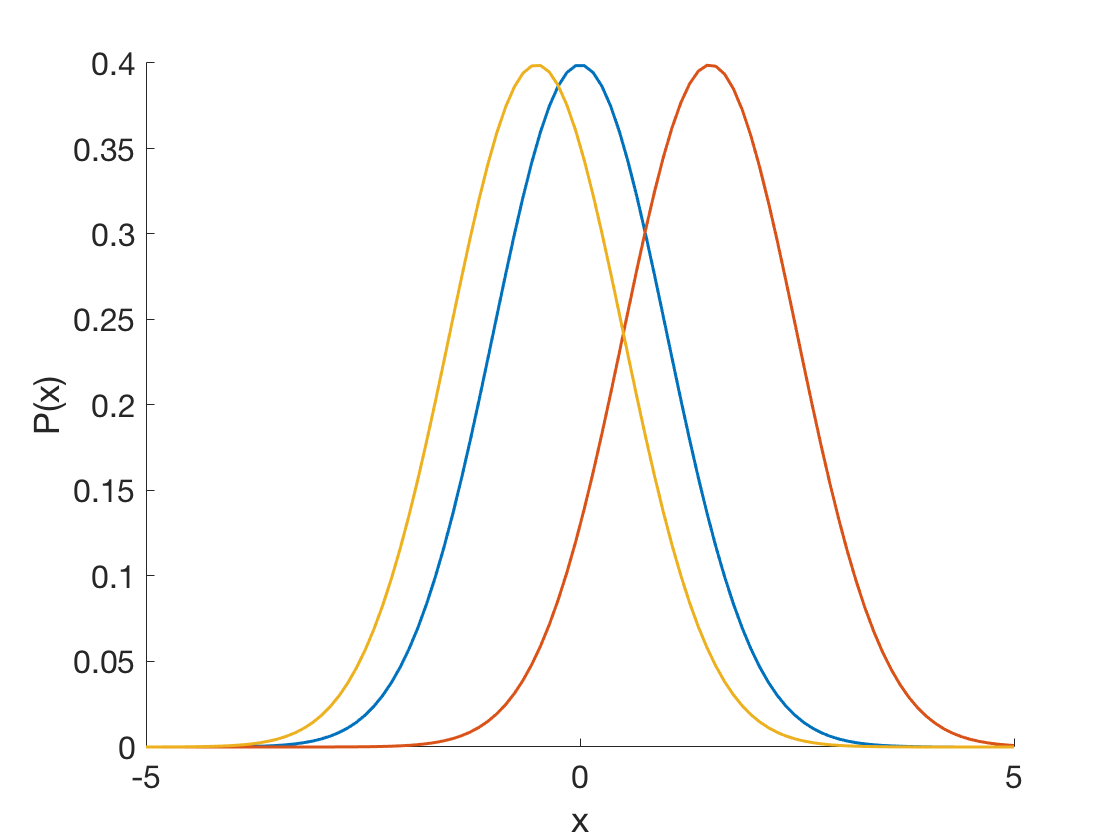

% Define a range of x values to evaluate the Gaussian PDF
x = linspace(-5, 5, 100);

% Define different mean values
mu = [0, 1.5, -0.5];

% Plot both curves on the same axis
figure
hold on
% Loop through the different means
for i=1:length(mu)
    % Compute the probability density function (PDF) for a Gaussian distribution
    pdf = normpdf(x, mu(i), 1);
    % Plot the PDF
    plot(x, pdf, 'Linewidth', 1.5)
end %for

% Label axis
xlabel('x')
ylabel('P(x)')

% Change font size
set(gca, 'FontSize', 16)
hold off

Technically speaking these parameters are said to have *translation invariance*. We can exemplify this with an example borrowed from Sivia's book. Let's imagine that you are trying to determine the position of the lighthouse near Nobska beach with respect to The Gemma (the MBL research boat) that is anchored at some position. All you are given are a series of estimates of the position$X$. The probability that the lighthouse lies in the infinitesimally small range between $x$ and $x + \delta x$ is given by


$$\lim_{\delta x \rightarrow 0} P(x \leq X \leq x + \delta x) \approx P(X = x) dX.$$


But whay if they told you that the data you were given was actually shifted by a distance $x_o$ because they didn't account for the length of the boat itself or some other mistake that could have happened. That would mean that every single datum$X$you were given was actually$X + x_o$. That shouldn't affect the probability of the lighthouse of being located on a small range since all we did was translated all the points together by the same factor (that's where the location invariance comes from). What this would imply is that


$$P(X)dX = P(X+x_o)d(X + x_o).$$


Since $x_o$ is a constant we can define that $d(X + x_o) = dX$. **Therefore it must be true that **$P(X) = P(X + x_o)$**, and this can only be possible if **$P(X)$**is a constant for all values of **$X$**.** That's why location parameters are given what is called a ***uniform prior***, menaing that before performing the measurement it is equaliy likely to be at any value within the allowed span.

**Scale parameters**

Scale parameters usually determine the shape of the distributions. Going back to the graphical example we had before with the Gaussian curves, the variance $\sigma^2$ is a scale parameter since shifting its value does not translate the position of the curve, but changes the width of the distribution. Again let's quickly plot an example for different variance values.

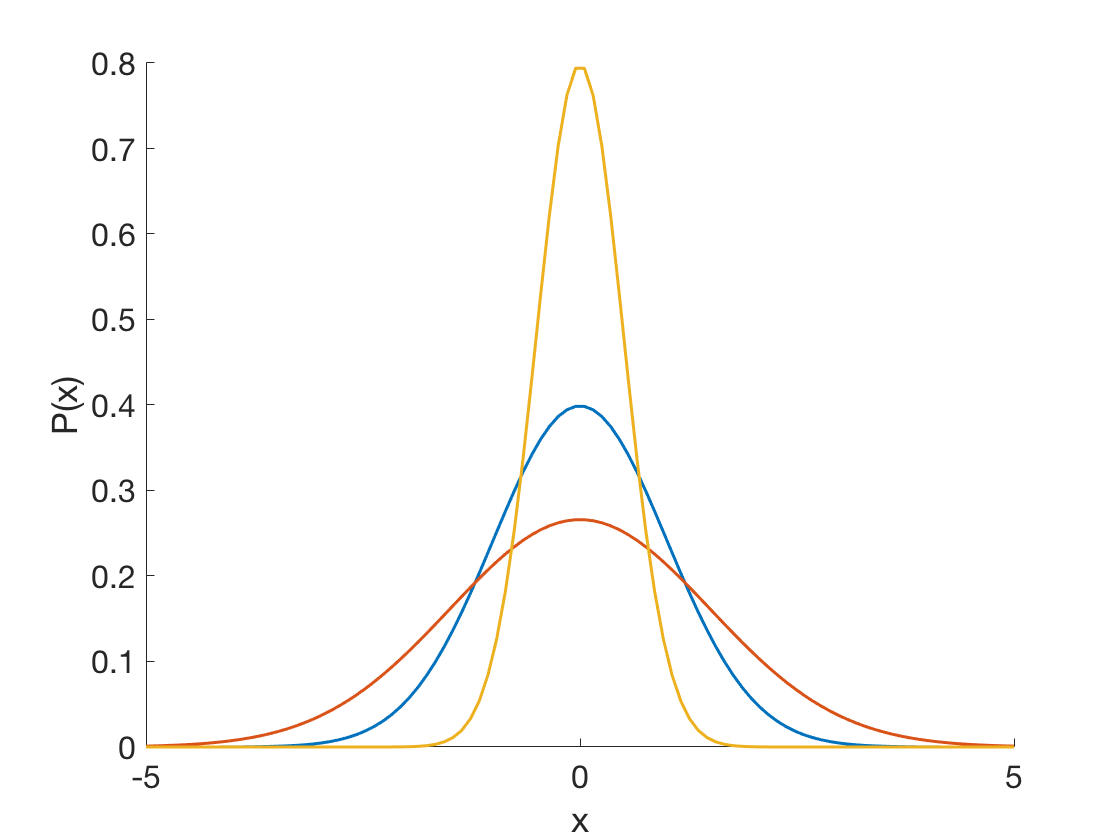

% Define a range of x values to evaluate the Gaussian PDF
x = linspace(-5, 5, 100);

% Define two different mean values
sigma = [1, 1.5, 0.5];

% Plot both curves on the same axis
figure
hold on
% Loop through each of the vlaues for the standard deviation
for i=1:length(mu)
    % Compute the PDF for a Gaussian distribution
    pdf = normpdf(x, 0, sigma(i));
    % Plot the PDF
    plot(x, pdf, 'Linewidth', 1.5)
end %for

% Label axis
xlabel('x')
ylabel('P(x)')

% Change font size
set(gca, 'FontSize', 16)
hold off

These parameters are said to have *scale invariance*. We can again use the lighthouse example to explain what this means. Let's say that I took the data in what Jane Kondev likes to call "communist units", for example meters. You naivly thought that I was giving you "freedom units", i.e. feet, and the numbers I was giving you couldn't be right. When we realize why you were having such a hard time with the data we realize that all what you needed was to multiply each datum$X$ by a constant $\beta$ to convert back to feet. But if I analyze my data in meters and you analyze it in feet it should be true that in a small interval between $X$and$X + \delta X$the probabilities we get are the same as long as the intervals are equal. We write that mathematially as


$$P(X)dX = P(\beta X)d(\beta X),$$


where again $\beta$ is the conversion factor between units (our scale parameter). Since $\beta$ is a constant it follows that $d(\beta X) = \beta dX$. That implies that


$$P(X)dX = P(\beta X)\beta dX.$$


Only if I set $P(X)$ to be proportional to $1 / X$this equality will be satisfied. You can see that by substituting $P(X)$as


$$\frac{1}{X} dX = \frac{1}{\beta X}\beta dX.$$


This is called the [Jeffreys' prior](https://en.wikipedia.org/wiki/Jeffreys_prior) and is the most common uninformative prior for scale parameters. 

Having given a short introduction to selection of prior probabilities let's choose a prior for both of our parameters.

## The prior of each parameter is indpendent of the other parameter.

Since we chose a Gaussian likelihood we had to add an extra parameter $\sigma$ to our posterior. Given there is not a clear connection I can think of between this new parameter and the binding energy $\Delta\epsilon_r$ it is safe to assume that they are both independent. This allows us to apply the mantra of independence again and write


$$P(\Delta\epsilon_r, \sigma) = P(\Delta\epsilon_r) \cdot P(\sigma).$$


## Uniform prior for the binding energy $\Delta\epsilon_r$

If we look at our likelihood again we note that $\Delta\epsilon_r$is involved in the numerator of the expression in the exponential. It is therefore acting as a location parameter that we will assign a uniform prior


$$P(\Delta \epsilon_r) = \left\{
\begin{array}{cl}
\frac{1}{\Delta\epsilon_r^\max - \Delta\epsilon_r^\min} & 
\text{for }\Delta\epsilon_r^\min \leq \Delta \epsilon_r \leq \Delta\epsilon_r^\max\\
0 & \text{otherwise}.
\end{array}
\right.$$


where $\Delta\epsilon_r^\max$ and $\Delta\epsilon_r^\min$ represent the boundaries that we set for our binding energy. The selection of these boundaries should make physical/biological sense. But since we will be computing a non-normalized posterior distribution this is just a **constant** that we will end up throwing to the proportionality constant.

## Jeffreys' prior for $\sigma$

Again if we stare at the likelihood we immediately recognize that $\sigma$ is in the denominator of the term in the exponential, so it is acting as a scale parameter. That means that we will assign it a Jeffres' prior, i.e.


$$P(\sigma) \propto \frac{1}{\sigma}.$$


# The full posterior probability $P(\Delta \epsilon_r, \sigma \mid D)$

Putting our likelihood and our prior together, the posterior probability looks like


$$P(\Delta \epsilon_r, \sigma \mid D) \propto 
\prod_{i \in D} 
\frac{1}{\sqrt{2 \pi \sigma^2}} 
\exp \left[ \frac{ \left( \text{fold-change}_\exp^{(i)} - 
\text{fold-change}_\text{theory}(R^{(i)}, \Delta \epsilon_r) \right)^2}{2 \sigma^2} \right] \cdot 
\frac{1}{\Delta\epsilon_r^\max - \Delta\epsilon_r^\min} \cdot 
\frac{1}{\sigma}.$$


There are a couple of algebraic manipulations we can do. First of all $\sigma$ does not have an index $(i)$, that allows us to take it out of the product raised to the $n$ power. To see this more clearly notice that $\prod_{i=1}^n a = a \cdot a \cdot a \cdots= a^n,$ for $a$ = constant.

Then we note that we can send the constants $\sqrt{2\pi}$ and the prior for the energy to the proportionality constant. With this we can rewrite the posterior as


$$P(\Delta \varepsilon_r, \sigma \mid D) \propto 
\frac{1}{\sigma^{n+1}} 
\exp \left[ \frac{ \left( \text{fold-change}_\exp^{(i)} - 
\text{fold-change}_\text{theory}(R^{(i)}, \Delta \epsilon_r) \right)^2}{2 \sigma^2} \right].$$


# Removing the nuisance parameter $\sigma$

To get rid of the nuisance parameter $\sigma
$ there is a standard procedure in probability theory that involves some heavy math machinery. What we can do to get rid of the parameter we don't care about is to integrate it out over all possible values


$$P(\Delta \varepsilon_r \mid D) = \int d\sigma\; P(\Delta \varepsilon_r \sigma \mid D).$$


Performing this type of integrals to marginalize parameters can be a very nasty task. As a matter of fact in most cases these integrals have no close form analytical solutions. That is one of the main reasons that historically made scientists choose frequentists methods rather than Bayesians. But in the era of modern computers this should not be a limitation. In the next tutorial I will show you how to use a incredibly powerful tool know as *Markov Chain Monte Carlo* sampling to numerically perform these integrals over parameters we don't care about.

For our particular case in which we had a uniform prior for the parameter we care about $\Delta\epsilon_r$ and a Jeffreys prior for the parameter imposed by our selection of the Gaussian likelihood $\sigma$ there exists a [close form solution for the integral](https://en.wikipedia.org/wiki/Student%27s_t-distribution#Bayesian_inference). Here we will just quote the result since it is not a trivial result. The marginalized posterior takes the form


$$P(\Delta \varepsilon_r \mid D) \propto 
\left[ \sum_{i \in D} 
\left( \text{fold-change}_\exp^{(i)} - 
\text{fold-change}_\text{theory}(R^{(i)}, \Delta \epsilon_r) \right)^2 \right]^{- \frac{n}{2}},$$


where $n \equiv |D|$ is the number of data points. This is call the *student-t* distribution*. *If you have heard of the frequentist method known as *Maximum -likelihood* or *minimization of the sum of the square of the residuals* this functional form might ring a bell. Whenever someone uses those approaches for parameter inference they are implicitly assuming that the residuals follow a Gaussian likelihood as we did.

# Working with the $\log$ posterior

Many times when managing very small numbers (such as probabilities) is much easier for analytical and numerical reasons to work in log scale. In our example if we take the log of this posterior we find that


$$\mathcal{L}(\Delta\epsilon_r) \equiv \ln P(\Delta \varepsilon_r \mid D, I) \propto
- \frac{n}{2} 
\log \left[ \sum_{i \in D} 
\left( \text{fold-change}_\exp^{(i)} - 
\text{fold-change}_\text{theory}(R^{(i)}, \Delta \epsilon_r) \right)^2 \right].$$


# Evaluating the log posterior function

Now that we have the theory in place we can just compute the posterior probability for the binding energy. Let us use O2 as a first illustrative example. We have written a function `logPosterior` that computes the non-normalized posterior distribution. This function takes 3 arguments

- `foldChangeExp`: Experimental fold-change measured for those given values of repressors.

- `R`: Number of repressors.

- `epsilonR`: Repressor binding energy.

We will compute the posterior probability for energies between -14.5 and -13.5 $k_BT$.

% Select rows that have operator O2 and a positive number of repressors (removing ∆lacI strain)
O2Rows = df.operator == "O2" & df.repressors > 0;

% Use the boolean array to extract the data for O2 from the general data frame.
% We will extract only the columns we care about to keep it simple.
dfO2 = df(O2Rows, {'operator', 'repressors', 'fold_change'});

% Define energies to compute the posterior probability on.
energies = linspace(-14.5, -13.5, 500);

% Initialize array to save the log posterior probability
logP = zeros(1, length(energies));

% Loop through the energies computing the log probability at each step.
for i=1:length(logP)
    logP(i) = logPosterior(dfO2.fold_change, 2 * dfO2.repressors, energies(i));
end

% Scale the probability to be maximum at 1 (since is a non-normalized distribution)
logP = logP - max(logP);

We can now plot and see **the whole distribution!** This is part of the power of the Bayesian approach. We don't have to stare only at one fixed value for our parameter, but we can get a complete distribtion of the possible values that the parameter can take.

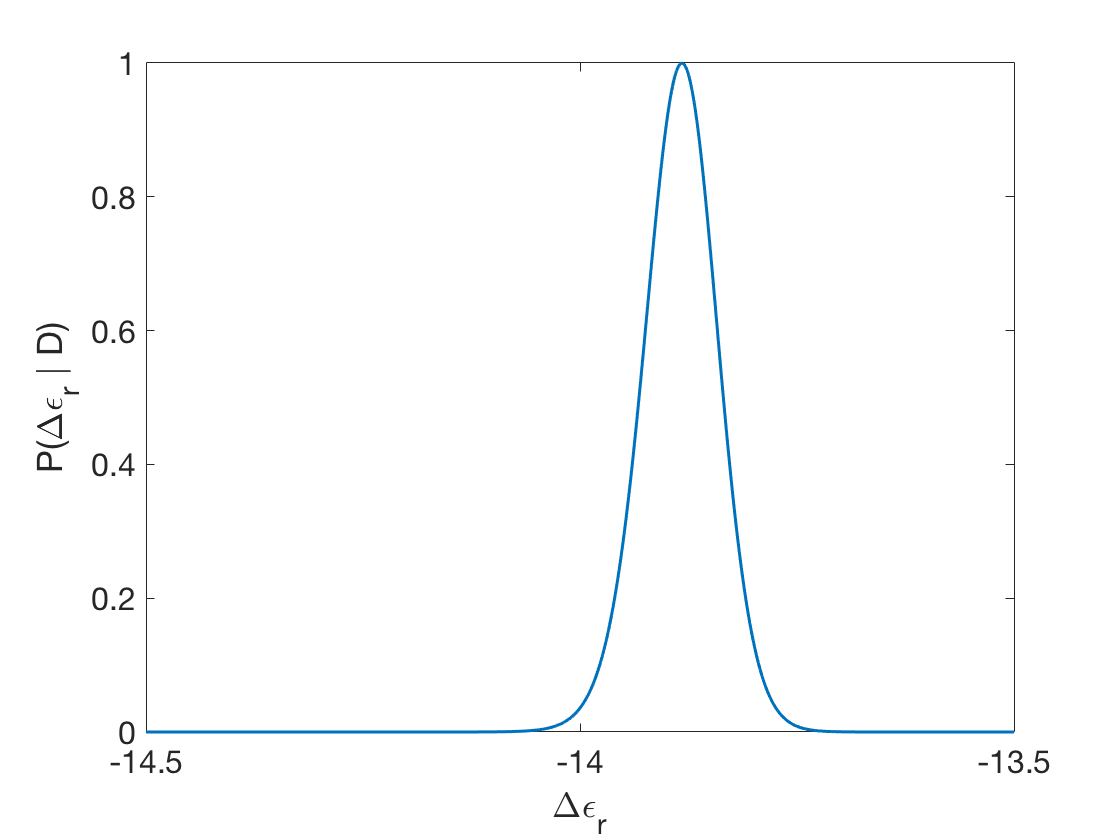

% Plot the energies vs probability
% remember to exponentiate since we computed the log posterior!
plot(energies, exp(logP), 'Linewidth', 1.5)

% Label axis
xlabel('\Delta\epsilon_r')
ylabel('P(\Delta\epsilon_r \mid D)')
% Cahnge font size
set(gca, 'FontSize', 16)

# Finding the most likely parameter value

Let's say we want to find where the peak